# Sensitivity analysis

Copyright (C) 2022  Bolic

  This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIAC AND RESPIRATORY MONITORING DEVICES.

% Changing the path from main_folder to a particular chapter
main_path=fileparts(which('Main_Content.mlx'));
if ~isempty(main_path)
    %addpath(append(main_path,'/Chapter2'))
    cd (append(main_path,'/Chapter2/Sensitivity'))
    addpath(append(main_path,'/Service'))
end
SAVE_FLAG=0; % saving the figures in a file

## Introduction

Let us analyze what parameter affects the output the most for the case of a differential amplifier. The amplifier is shown in the figure below.

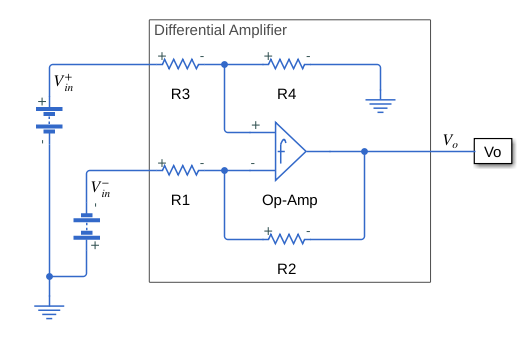

## Data Generation

`sdo.getParameterFromModel(modelname,paramname)` will creates an object from the Simulink model parameter that can be tuned to satisfy design requirements during optimization.  

model_name = 'Diff_ampl';
open_system(model_name);

R1 = sdo.getParameterFromModel(model_name, 'R1');
% R1.Minimum=R1.Value*1.01;
% R1.Maximum=R1.Value*0.99;

R2 = sdo.getParameterFromModel(model_name, 'R2');
% R2.Minimum=R2.Value*1.01;
% R2.Maximum=R2.Value*0.99;

R3 = sdo.getParameterFromModel(model_name, 'R3');
% R3.Minimum=R3.Value*1.01;
% R3.Maximum=R3.Value*0.99;

R4 = sdo.getParameterFromModel(model_name, 'R4');
% R4.Minimum=R4.Value*1.01;
% R4.Maximum=R4.Value*0.99;


%V = sdo.getParameterFromModel(model_name, 'V');
% V.Minimum=V.Value*1.01;
% V.Maximum=V.Value*0.99;

### Identifying Type of Distribution 

 Distributions of uncertain parameters will be identifiied and if they are not specified, uniform distribution is considered.


v1=[R1; R2; R3; R4];
ps1 = sdo.ParameterSpace(v1);
R1=setDistribution(ps1,'R1',makedist('normal',R1.Value, 0.005*R1.Value));
R2=setDistribution(ps1,'R2',makedist('normal',R2.Value, 0.005*R2.Value));
R3=setDistribution(ps1,'R3',makedist('normal',R3.Value, 0.005*R3.Value));
R4=setDistribution(ps1,'R4',makedist('normal',R4.Value, 0.005*R4.Value));

### Generating Samples

1000 samples from the parameter space will be generated. 

rng default;   % for reproducibility
ParamValues  = sdo.sample(ps1, 100); % uniform sampling
%sdo.scatterPlot(x);

SignalMatching_1 = sdo.Experiment('Diff_ampl');
t = [0;2];
y = [2;2];

% 
% %%
% % Specify the measured experiment output data.
SignalMatching_1_Sig_Output = Simulink.SimulationData.Signal;
SignalMatching_1_Sig_Output.Values    = timeseries(y,t);
SignalMatching_1_Sig_Output.BlockPath = 'Diff_ampl/Mux';
SignalMatching_1_Sig_Output.PortType  = 'outport';
SignalMatching_1_Sig_Output.PortIndex = 1;
SignalMatching_1_Sig_Output.Name      = 'Diff_ampl/Mux:1';
SignalMatching_1.OutputData = SignalMatching_1_Sig_Output;

% Sig_Info = Simulink.SimulationData.SignalLoggingInfo;
% Sig_Info.BlockPath = 'Diff_ampl/Meas 1';
% Sig_Info.LoggingInfo.LoggingName = 'Sig';
% Sig_Info.LoggingInfo.NameMode = 1;
% 
% Simulator.LoggingInfo.Signals = Sig_Info;

%%
% Create a model simulator from an experiment
Simulator = createSimulator(SignalMatching_1);

### Create Evaluation Objective Function


%% Create Evaluation Objective Function
%
% Create a function that is called for each combination of parameters
% being varied, to compute the cost.
%
% Use an anonymous function with one argument that calls Diff_ampl_evalFcn.
evalfcn1 = @(P) Diff_ampl_evalFcn(P,Simulator,SignalMatching_1);

%% Evaluation Options
%
% Specify evaluation options.
Options = sdo.EvaluateOptions;
Options.EvaluatedModel = Simulator;

%% Evaluate the Model
%
% Call sdo.evaluate with the objective function handle, parameters to
% vary, parameter values, and options.

[EvalResult,Info] = sdo.evaluate(evalfcn1,ps1,ParamValues,Options);

## Run Statistical Analysis

Sensitivity analysis is performed in Simscape for the differential amplifier

sensitivity = sensitivityStatistics(ParamValues,EvalResult)

sensitivity = struct with fields:
                   Correlation: [4×1 table]
               RankCorrelation: [4×1 table]
            KendallCorrelation: [4×1 table]
        StandardizedRegression: [4×1 table]
    RankStandardizedRegression: [4×1 table]
            PartialCorrelation: [4×1 table]
        RankPartialCorrelation: [4×1 table]


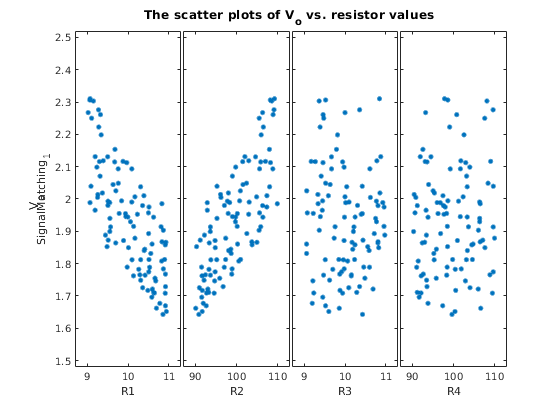

sdo.scatterPlot(ParamValues,EvalResult)
ylabel('V_o')
    title('The scatter plots of V_o vs. resistor values')
   if SAVE_FLAG==1

       exportgraphics(gcf,'Fig1.12.jpg', 'Resolution',600);
   end
sensitivity.Correlation

ans = 4×1 table
          SignalMatching_1
          ________________

    R1        -0.76609    
    R2         0.76445    
    R3       -0.053677    
    R4         0.06969    


### Computing Statistics

This function evaluates design requirements

function Vals = Diff_ampl_evalFcn(P,Simulator,SignalMatching_1)
%DIFF_AMPL_EVALFCN
%
% Function called at each iteration of the evaluation problem.
%
% The function is called with a set of parameter values, P, and returns
% the evaluated cost, Vals.
%
% See the sdoExampleCostFunction function and sdo.evaluate for a more
% detailed description of the function signature.
%

%%
% Define a signal tracking requirement to compute how well the model
% output matches the experiment data.
%r = sdo.requirements.SignalTracking;
%%
% Update the experiment(s) with the estimated parameter values.
SignalMatching_1 = setEstimatedValues(SignalMatching_1,P);

%%
% Simulate the model and compare model outputs with measured experiment
% data.
Simulator = createSimulator(SignalMatching_1,Simulator);
strOT = mat2str(SignalMatching_1.OutputData.Values.Time);
Simulator = sim(Simulator, 'OutputOption', 'AdditionalOutputTimes', 'OutputTimes', strOT);

SimLog = find(Simulator.LoggedData,get_param('Diff_ampl','SignalLoggingName'));
Sig = find(SimLog,SignalMatching_1.OutputData.Name);

%Vals.SignalMatching_1 = evalRequirement(r,timeseries(getdatasamples(Sig.Values,[2:60])),SignalMatching_1.OutputData.Values);
Vals.SignalMatching_1 =mean(Sig.Values.Data(:,2:end));
end


Scatter plot showing the relationship between outputs and the values of the resistors are created. 

Correlation coefficients computed between the values of each resistor and the output are computed as well as standardized regression coefficients 

This will allow for the the appropriate selection of resistors for the circuit as it can be seen the output of the system is much more affected by changes in certain resistors in comparison to others. 


function sensitivity = sensitivityStatistics(x,y)
%SENSITIVITYSTATISTICS
%
% Compute sensitivity analysis statistics for the  model.
%
% The function returns sensitivity analysis statistics, sensitivity,
% indicating which parameters, x, have the most influence on the
% requirements, y.
%
% The input argument, x, defines the parameters.  If omitted, the
% parameters specified in the function body are used.
%
% Modify the function to change the analysis techniques.
%
% Auto-generated by SSATOOL on 29-Dec-2020 13:38:31.
%

%% Specify Analysis Variables
%
% Specify parameters and requirements.
if (nargin < 1)  ||  isempty(x)
    x = getData('x');
end

if (nargin < 2)  ||  isempty(y)
    y = getData('y');
end


%% Statistics Options
%
% Specify options for statistical analysis
opts = sdo.AnalyzeOptions;
opts.Method =  {'Correlation', 'StandardizedRegression', 'PartialCorrelation'};
opts.MethodOptions = {'Linear', 'Ranked', 'Kendall'};

%% Compute Statistics
%
% Call sdo.analyze with the parameters and requirements, to determine which
% parameters most influence the requirements.
sensitivity = sdo.analyze(x,y,opts);
end

